clear
Gs2=tf([1],[1 3 4 2])

Gs2 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



x0 = [1,0,0]; %
fun = @ident;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag] = fminsearch(fun,x0,options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          64.0002         
     1            4          56.6079         initial simplex
     2            5          56.6079         reflect
     3            7          52.1993         expand
     4            9          43.0408         expand
     5           10          43.0408         reflect
     6           12          31.1107         expand
     7           14          22.3218         expand
     8           15          22.3218         reflect
     9           17          9.73737         expand
    10           19          5.66334         expand
    11           21          2.64245         expand
    12           23         0.237846         expand
    13           25        0.0036257         expand
    14           26        0.0036257         reflect
    15           28        0.0036257         contract outside
    16           30        0.0036257         contract inside
    17           32        0.0036

x =     4.9680   -0.0092   -0.0108


fval = 9.7822e-11

exitflag = 1

G1=tf([1],[1 3 4 2]) % System

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



C = pid(x(1),0,x(3)) % Controller

C =
 
             
  Kp + Kd * s
             

  with Kp = 4.97, Kd = -0.0108
 
Continuous-time PD controller in parallel form.



%G2=tf([0 1],[x(1) x(2) x(3)])
G1

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



G2_loop=feedback(C*G1,1)

G2_loop =
 
       -0.01084 s + 4.968
  -----------------------------
  s^3 + 3 s^2 + 3.989 s + 6.968
 
Continuous-time transfer function.



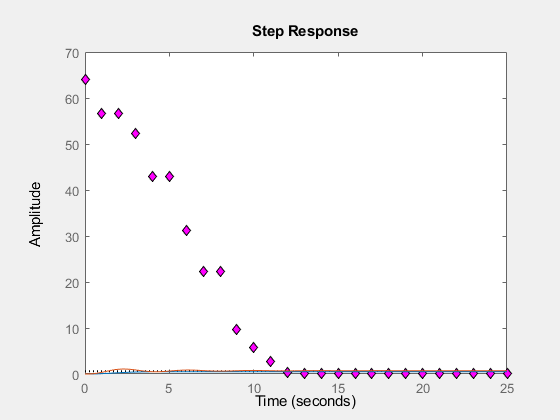

%step(G1);
step(G1,G2_loop);

G2=C*G1;
[Gm,Pm,Wcg,Wcp] = margin(G2);
%Gs=feedback(C*G1,1)
b=G2_loop.Numerator{1, 1};
a=G2_loop.Denominator{1,1};
Gm

Gm = 2.0000

C

C =
 
             
  Kp + Kd * s
             

  with Kp = 4.97, Kd = -0.0108
 
Continuous-time PD controller in parallel form.



[z,p,k] =tf2zp(b,a)

z = 458.2743

p =   -2.5154 + 0.0000i
  -0.2423 + 1.6466i
  -0.2423 - 1.6466i


k = -0.0108

%Kp = x(1)
%Ki = x(2)
%Kd = x(3)

function blad = ident(x)
t=0:0.01:10;
G1=tf([1],[1 3 4 2]);
C = pid(x(1),0,x(3)); % Controller
G2=C*G1;
[Gm,Pm,Wcg,Wcp] = margin(G2);
e = (Gm-2)^2;
blad= e;
end